# Zadanie 1

clc; clear; close all;
nfontslatex = 18;
nfonts = 14;
k_max = 35;

file = load('LM01Data.mat');
y = file.y;
t = file.t;

h = @(x,t) x(1)*sin(x(2)*t+x(3));
f = @(x) x(1)*sin(x(2)*t+x(3))-y;
x0 = [1.0, 100*pi, 0.0]'; % initial values of model parameters
n = length(x0);

figure
plot01 = plot(t,y,"s","MarkerEdgeColor","r","MarkerFaceColor","r");
hold on
tPlot = linspace(t(1),t(end),1e+3)';
plot02 = plot(tPlot,h(x0,tPlot),"b","LineWidth",2);
grid on

J = @(x) [sin(x(2)*t+x(3)) x(1)*t.*cos(x(2)*t+x(3)) x(1)*cos(x(2)*t+x(3))];
X = zeros(n,k_max+1);
X(:,1) = x0;
L = zeros(k_max, 1);
L(1) = 1.0;
for k = 1:k_max
    x = X(:,k);
    xNew = x - ((J(x)'*J(x)) + L(k)*eye(n))\J(x)'*f(x);
    if ( norm(f(xNew)) < norm(f(x0)) )
        X(:,k+1) = xNew;
        L(k + 1) = 0.8*L(k);
    else
        X(:,k+1) = x;
        L(k + 1) = 2*L(k);
    end
end
xOptimal = X(:,end);

plot(1:k_max, L(1:end-1), '.black');


X_norm = zeros(k_max, 1);
for i = 1:k_max
    X_norm(i) = norm(f(X(:, i)))^2;
end
figure
plot(1:k_max, X_norm, '.black');

# Zadanie 2

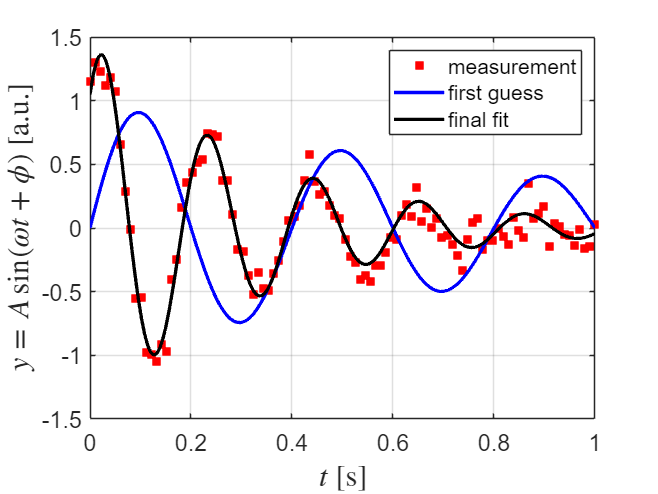

clc; clear; close all;
nfontslatex = 18;
nfonts = 14;
k_max = 25;

file = load('LM04Data.mat');
y = file.y;
t = file.t;

h = @(x,t) x(1) * exp(-x(4) * t) .* sin(x(2) * t + x(3));
f = @(x) x(1) * exp(-x(4) * t) .* sin(x(2) * t + x(3)) - y;
x0 = [1.0, 5*pi, 0.0, 1.0]';
n = length(x0);

J = @(x) reshape([
    exp(-x(4) * t) .* sin(x(2) * t + x(3));
    x(1) * exp(-x(4) * t) .* t .* cos(x(2) * t + x(3));
    x(1) * exp(-x(4) * t) .* cos(x(2) * t + x(3));
    -x(1) * t .* exp(-x(4) * t) .* sin(x(2) * t + x(3));
], [100, 4]);

figure
plot01 = plot(t,y,"s","MarkerEdgeColor","r","MarkerFaceColor","r");
hold on
tPlot = linspace(t(1),t(end),1e+3)';
plot02 = plot(tPlot,h(x0,tPlot),"b","LineWidth",2);
grid on

X = zeros(n,k_max+1);
X(:,1) = x0;
L = zeros(k_max, 1);
L(1) = 1.0;
for k = 1:k_max
    x = X(:,k);
    xNew = x - ((J(x)' * J(x)) + L(k) * eye(n)) \ J(x)' * f(x);
    if ( norm(f(xNew)) < norm(f(x0)) )
        X(:,k+1) = xNew;
        L(k + 1) = 0.8*L(k);
    else
        X(:,k+1) = x;
        L(k + 1) = 2*L(k);
    end
end
xOptimal = X(:,end);

plot03 = plot(tPlot,h(xOptimal,tPlot),"k","LineWidth",2);
legend([plot01,plot02,plot03],"measurement", "first guess", "final fit")
set(gca,"FontSize",nfonts);
ylabel("$y = A\sin(\omega t + \phi)$ [a.u.]","Interpreter","Latex","FontSize",nfontslatex)
xlabel("$t$ [s]","Interpreter","Latex","FontSize",nfontslatex)

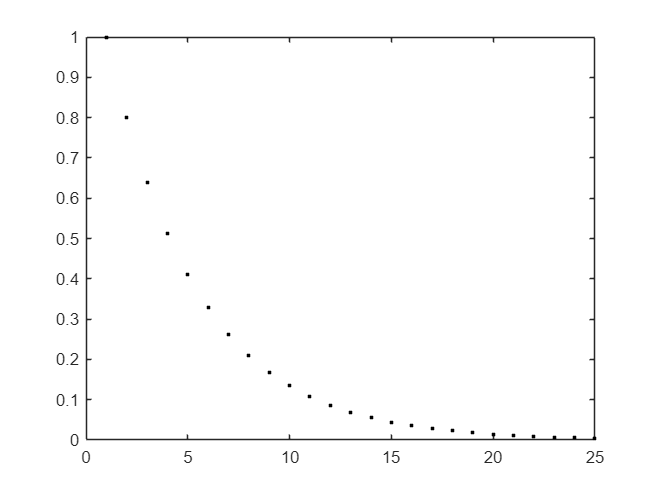


figure
plot(1:k_max, L(1:end-1), '.black');

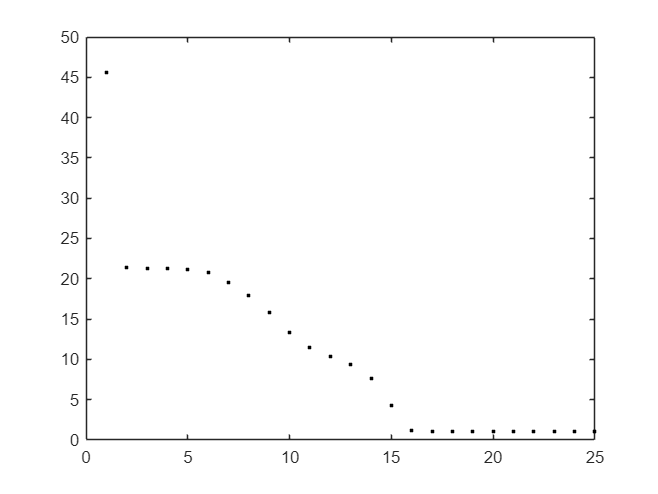



X_norm = zeros(k_max, 1);
for i = 1:k_max
    X_norm(i) = norm(f(X(:, i)))^2;
end
plot(1:k_max, X_norm, '.black');